# Using James' Fancy Toolbox for Reaction Mass AUV

Reaction mass mounted below CoG and CoG below CoB.

Concentrating just on manoeuvring for now, can add drag forces from motion in x,y,z later

**NB: this now considers pitch and roll, image below needs updating :-) **

**(WM: Done. Though should positive theta be a pitch ****up****, to keep in line with right-hand rule norms?)**

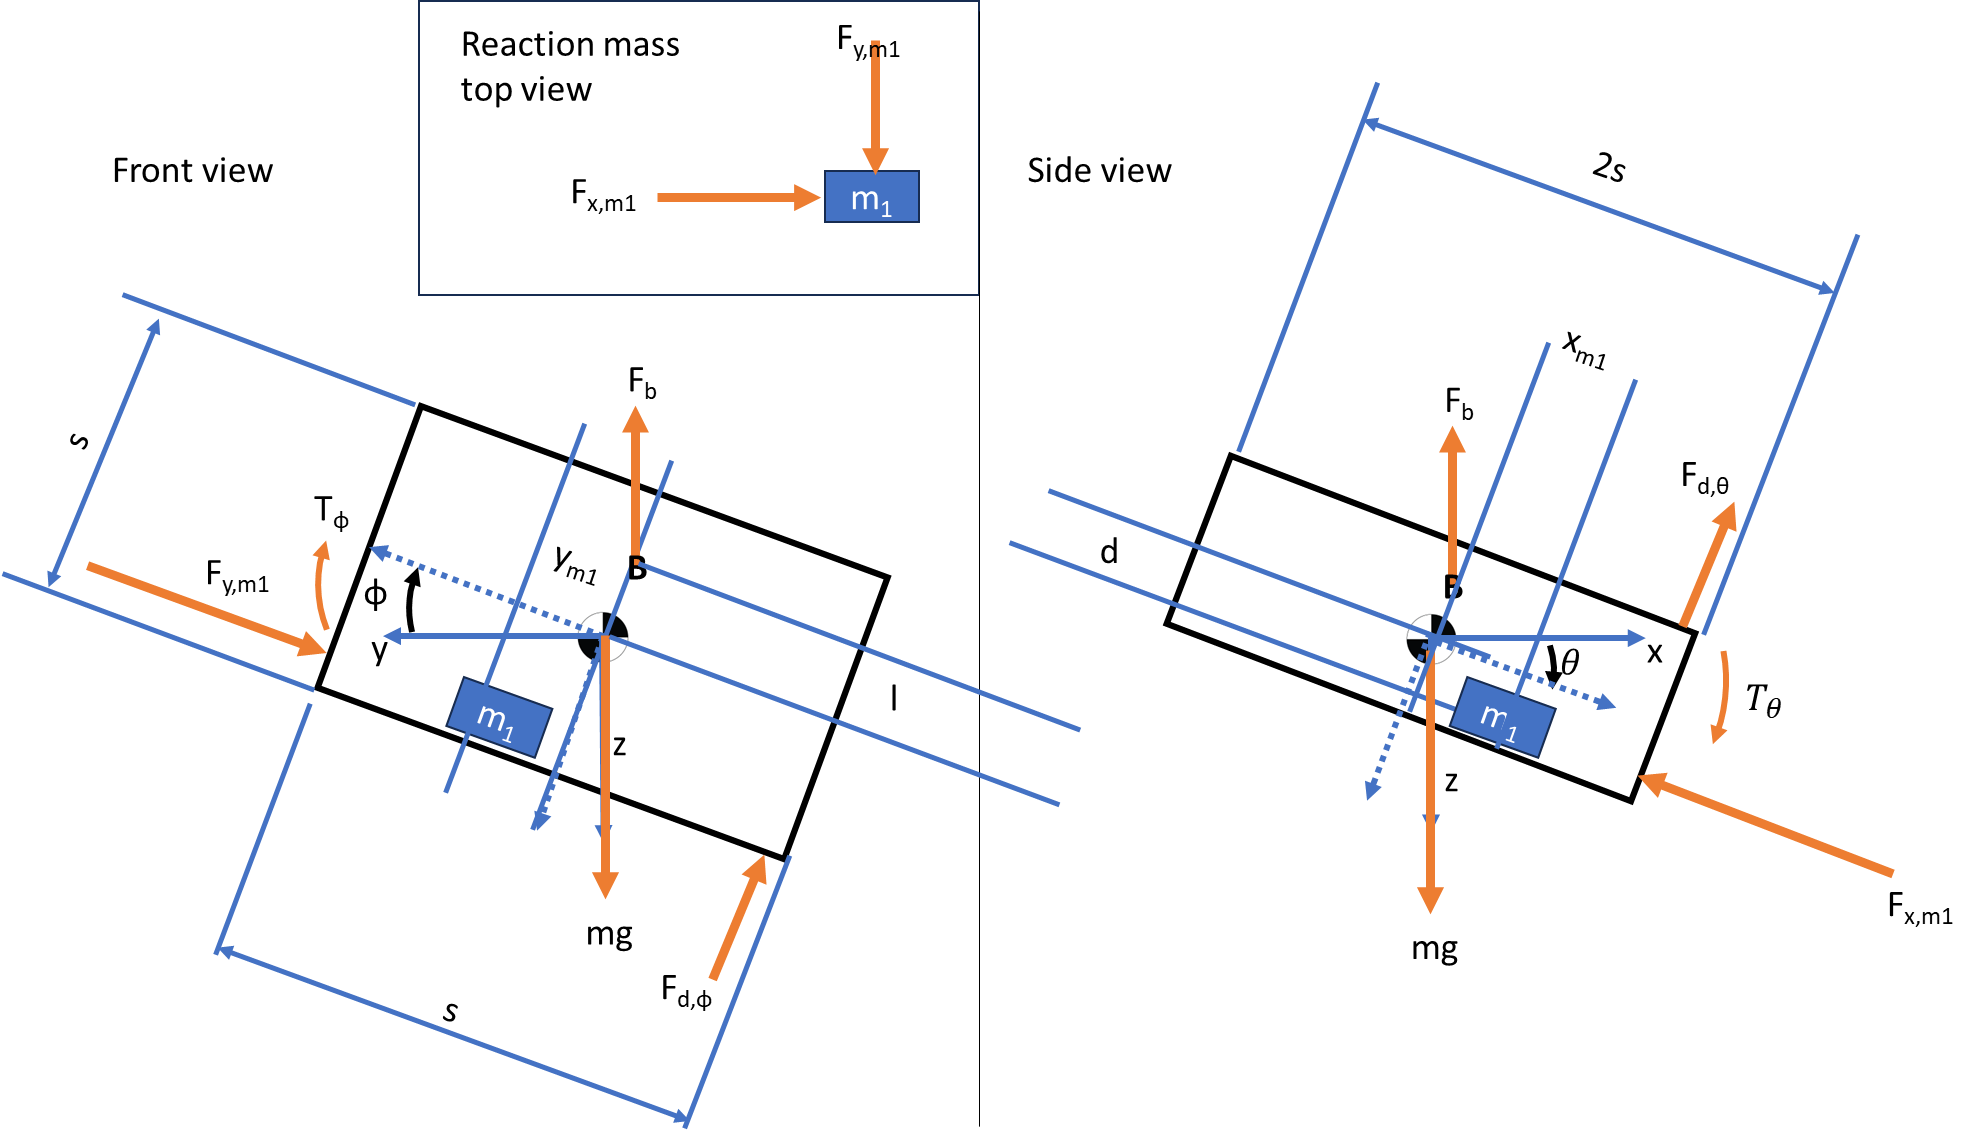

% Reaction mass AUV example
% theta - pitch angle;  JF - have updated these to follow the same
% convention we use for motorbikes, unsure if any convention for AUVs?
% phi - roll angle;
% x_m - relative reaction mass location in x;
% y_m - relative reaction mass location in y
syms theta(t) phi(t) x_m(t) y_m(t)
% reaction force inputs: F_x, F_y
syms F_x F_y T_theta T_phi

% define generalised co-ords:
q(t) = [theta(t) phi(t) x_m(t) y_m(t)];
% define system inputs:
U = [T_theta; T_phi; F_x; F_y];         % JF: this was the wrong size, which was why functionalderivative() was failing

% parameters (JF: I changed notation a little, mostly because _ makes a subscript in symbolic toolbox)
params = struct;
syms m M s d l g C_d rho
params.m = 1; % reaction mass mass
params.M = 15; % AUV mass
params.s = 0.5; % AUV half-length
params.l = 0.05; % height of CoB above CoM
params.d = 0.1; % distance below *CoM* for reaction mass
params.g = 9.81; % gravitational acceleration
params.C_d = 1; % coefficient of drag for rotational motion - use 1 for now
params.rho = 1020;      % JF: density of seawater, for bouyancy force

## Kinematics

Frames of reference: world frame, body frame and reaction mass frame 

(JF: we also have an intermediate frame between rotations, and let's remove the reaction mass frame since only the postition of this mass matters, so let's just consider it as a point mass that is defined w.r.t. the body frame)

WM: There is some detail around reference frames here as mentioned by JF. The CoB has to be in the middle of the AUV because physics, but we have some flexibility with the position of the CoM. Do we define everything in terms of the CoM reference frame (as presently), or redefine everything using the CoB reference frame and use parallel axes theorem to find the correct inertia matrix

$J^{\prime } =J_{\textrm{CoM}} +m\ldotp l$ where m is the mass and l is the distance of the CoM below the CoB.

Leaving everything in CoM co-ords makes some sense, as any rotations of the AUV will be about the CoM, rather than the CoB, so things are likely simpler in CoM co-ords. In general it makes sense to have the CoM below the CoB, so the AUV is self-righting. I guess it depends on whether any external forces (we might want to add thrust forces) act through the CoB or CoM.

M_01 = rotY(-theta); % pitch from zero point

'rotY' is used in the following examples:
  Code Generation for a Deep Learning Simulink Model That Performs Lane and Vehicle Detection
  Lane and Vehicle Detection in Simulink Using Deep Learning
  Lane and Vehicle Detection in ROS Using YOLO v2 Deep Learning Algorithm
  Code Generation for Deep Learning Simulink Model That Performs Lane and Vehicle Detection

M_12 = rotX(phi); % roll (now in rotated frame defined by the pitch angle)
M_02 = simplify(M_01*M_12); % from world to AUV body (JF: No, this is from AUV body to world :-) WM:🙄)
% CoG points
p_m = M_02*[x_m(t);y_m(t);d;1]; % <--- James to check - position of reaction mass CoM (JF: updated! WM:❤️)
p_M = M_02*[0;0;0;1];   % JF: AUV mass at origin of body frame (could ignore, but included for completeness)
p_b = M_02*[0;0;-l;1];   % JF: centre of bouyancy position in body frame (note z positive DOWN)

## Dynamics

% moments of inertia
J = cuboidInertia(M,s*2,s,s); % AUV inertia s*2 long, s wide, s deep
% J_2 = cuboidInertia(m,0.05,0.05,0.05); % inertia of reaction mass: 5cm x 5cm x 5cm
% JF: let's just make this a point mass instead, much easier, and if we really 
% did care about the inertia we could just add it to the AUV body inertia anyway
% WM: Sounds reasonable, a nice simplification for now.
% WM: See discussion above. These are the moments of inertia about the CoM
% which we are assuming is _below_ the CoB (and therefore below the
% centroid of the AUV).

% velocity of reaction mass
v_m = simplify(diff(p_m,t))

% Angular velocities of theta and phi (copy-pasted from James' code)
M_02 = M_02(t); R_02 = M_02(1:3,1:3);   % Rotation matrix 
Omega2 = simplify(diff(R_02.',t)*R_02);     % % roll velocity using angular velocity tensor 
% JF: there was previously a typo here - should be diff(A,t)*A.' BUT A is actually R_02.' in this case!

omega2 = [Omega2(3,2);Omega2(1,3);Omega2(2,1)]     % angular velocity (pseudo)vector

% Kinetic energy of whole mechanism in world frame (JF: Unlike the SCARA example,
% rotations are not coplanar, so must transform the inertia tensors!)
T = massKE(m, v_m) + ... % reaction mass KE
    rotationKE(J,omega2)  % AUV rotation KE

T = simplify(expand(T))

% z-coordinates of reaction mass, AUV mass (at origin), and bouyancy centre
z_m = [0,0,1,0]*p_m % <-- doesn't seem right  (JF: checked it, looks okay, just selects the 'z' component)
z_M = [0,0,1,0]*p_M
z_b = [0,0,1,0]*p_b

% Potential energy of whole mechanism 
Vg = -m*g*z_m - M*g*z_M;      % gravity part (JF: be careful here, z is DOWN)
Vol = 2*s^3;        % AUV volume for bouyancy
Vb = rho*Vol*g*z_b;     % potential due to bouyancy
V = Vg + Vb;

% Lagrangian and Euler-Lagrange equations
L = T - V;
L_p = subs(L, params);
% EOM = simplify(functionalDerivative(L_p,q(t))) == U
EOM = simplify(functionalDerivative(L,q(t))) == U         % this version will keep the parameters visible


WM: Note that these equations don't include the friction drag from the relative motion of the AUV against the water. I guess we would need to use some sleight-of-hand to add these forces to the Lagrangian. Another argument for perhaps doing Newtonian in the body frame and then translating to the world frame.

## Second order form of equations of motion

To understand them better, let's put the EOMs into the following form


$$M(q) \ddot{q} + c(q,\dot{q}) + g(q) = u$$


where 'u' is the vector of inputs, i.e. joint torques and forces, c(.,.) contains coriolis and centrifugal terms, g() is gravity and bouyancy.

% Mass matrix should be the same as the Jacobian w.r.t accelerations
M_nl = jacobian(lhs(EOM), diff(q(t),t,t))

% Gravitational part is what is left when no velocity or acceleration
g_nl = subs(lhs(EOM),[diff(q(t),t);diff(q(t),t,t)],[zeros(1,4);zeros(1,4)])
% Find coriolis and centrifugal terms by looking at what remains when 
% inertial and gravitational force terms are removed:
c_nl = subs(lhs(EOM),diff(q(t),t,t),zeros(1,4)) - g_nl

## Find equilibrium configurations for constant external torque

% JF - Look for equilibrium configurations (all terms disappear except g() and U):
syms Theta Phi X_m Y_m
equil = subs(g_nl,[theta phi x_m y_m],[Theta Phi X_m Y_m]) == U
eq = solve(equil,[T_theta T_phi F_x F_y]);
T_theta_eq = eq.T_theta
T_phi_eq = eq.T_phi
F_x_eq = eq.F_x
F_y_eq = eq.F_y

WM: Am I mis-interpreting something here? It looks like that, to maintain the given angular position in response to the external torque, a certain position of the masses is required *as well as* a force on the reaction mass in x and y. I guess that though this is an 'equilibrium' position, a torque would only be applied by the arm to the AUV when it is in motion, so the forces required would be time-varying. (We can't keep the mass in a given position *and *exhert a force on it at the same time - any force on it will cause it to move position.)

### Look at constant x_m and y_m with zero angles:

% WM: just to look at equilibriums and check I understand code
equil2 = subs(g_nl,[theta phi x_m y_m],[0 0 X_m Y_m]) == U
solve(equil2,[X_m Y_m F_x F_y])

This seems correct - we need to use the mass to apply enough torque to counteract the torques being imposed on the AUV

### Convert system to nonlinear state space form

% First convert to SS representation (JF: now working but slow - instead use second order or descriptor form?)
[EOM_rhs, S] = stateSpaceEquations(EOM, {theta phi x_m y_m});
% EOM_rhs


### Calculate stabilising state feedback gain u=Kx around some linearisation point

% then set operating point (should be an equilbrium point! - JF)
% %S =
%     Theta
% Theta_dot
%       Phi
%   Phi_dot
%       X_m
%   X_m_dot
%       Y_m
%   Y_m_dot
% S_op = [0; 0; 0; 0; 0; 0; 0; 0];  % corrected by JF - needs to include the derivative states too 
S_op = [5*pi/180; 0; 0; 0; 0; 0; 0; 0];  % if we use a nonzero OP, we will need a steady-state input

% % Find steady-state inputs required for equilibrium at this operating point:
Ueq = struct;
Ueq.T_phi = subs(subs(T_phi_eq, S, S_op), params);
Ueq.T_theta = subs(subs(T_theta_eq, S, S_op), params);
Ueq.F_x = subs(subs(F_x_eq, S, S_op), params);
Ueq.F_y = subs(subs(F_y_eq, S, S_op), params)

% A matrix from JF's inverted pendulum
A_nl = subs(jacobian(EOM_rhs, S), Ueq);
A_lin = subs(A_nl, S, S_op);

% B matrix also from JF inverted pendulum example
B_nl = subs(jacobian(EOM_rhs, U), Ueq);
B_lin = subs(B_nl, S, S_op);

A = double(subs(A_lin, params));
B = double(subs(B_lin, params));

% check controllability
Co = ctrb(A,B);
unco = length(A) - rank(Co)

% % simple LQR controller (from JF's code)
% Q = eye(8);     % updated to 8 states
% R = 1e-2;

% LQR to penalise only roll, pitch outputs and derivatives (do we really care where m1 is? - JF)
C = [diag([1e0,1e0,1e0,1e0]), zeros(4)];
Q = C'*C;
R = diag([1e-2,1e-2,1e-2,1e-2]);

K = -lqr(A,B,Q,R);
% check eigenvalues
eig(A + B*K)

### Create Simulink model


EOM_rhs = subs(EOM_rhs, params);
IC = '[5*pi/180; 0; -5*pi/180; 0; 0.1; 0; 0.1; 0]'; % initial conditions

U_op = double([Ueq.T_theta; Ueq.T_phi; Ueq.F_x; Ueq.F_y]);
stateFeedbackModel(EOM_rhs, S, U, IC, K, S_op, U_op)

